Importing the data from Excel

data = readmatrix('Winter.xlsx')

data =            1        1001         935
           2         967         923
           3         946         918
           4         939         931
           5         934         976
           6         952        1026
           7        1004        1167
           8        1095        1319
           9        1206        1327
          10        1276        1284


Inputs = data(:,1:2);
Target = data(:,3);

 Visulisation of Input and Target Load Data

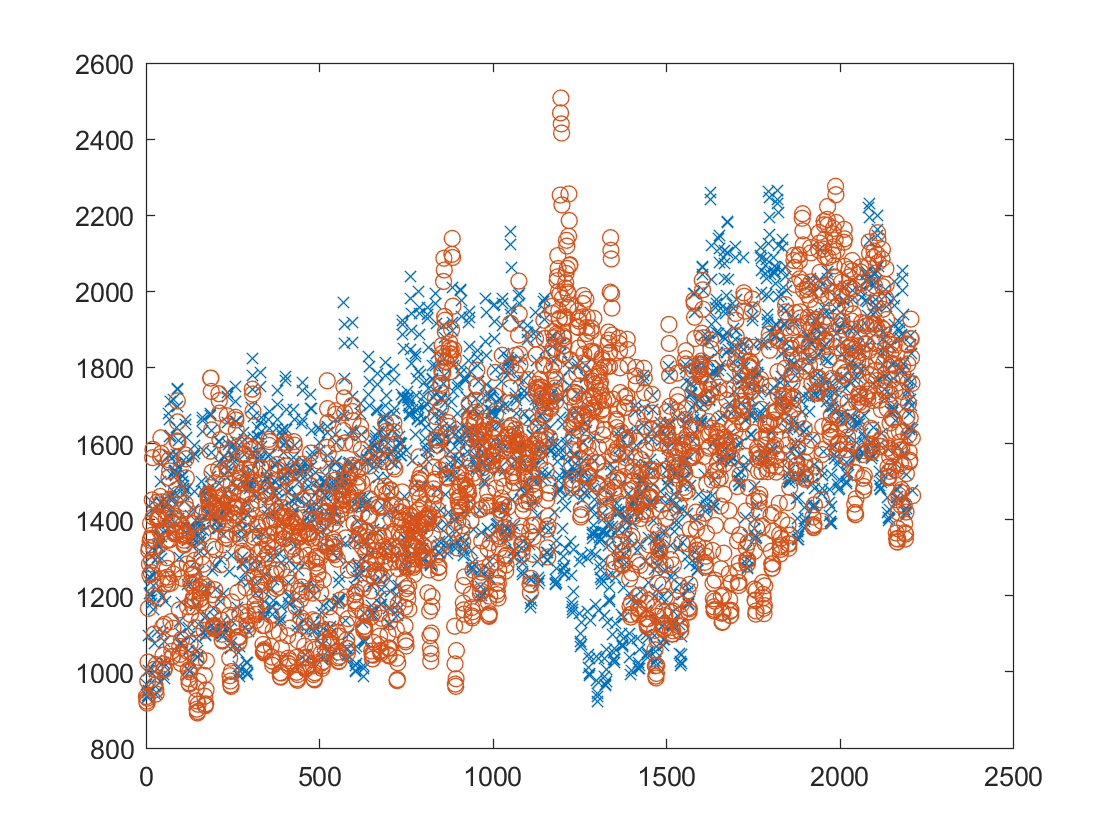

plot(Inputs(:,2),'x')
hold on
plot(Target,'o')
hold off

Training ANN using LM algorithm

Xt = Inputs';    %Transpose of input data
Yt = Target';    %Transpose of traget data
hiddenLayerSize = 500;   % number of neurons in a hidden layer
net = fitnet(hiddenLayerSize); % network builder

Dividing the data of Inputs and Target according to the Train data, Validation data and Test data.

net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
[net,tr] = train(net,Xt,Yt)


net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 2001
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      in

tr = struct with fields:
        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×1546 double]
          valInd: [1×331 double]
         testInd: [1×331 double]
            stop: 'Validation stop.'
      num_epochs: 10
       trainMask: {[1×2208 double]}
         valMask: {[1×2208 double]}
        testMask: {[1×2208 double]}
      best_epoch: 4
            goal: 0
          states: {'epoch'  'time'  'perf'  'vperf'  'tperf'  'mu'  'gradient'  'val_fail'}
           epoch: [0 1 2 3 4 5 6 7 8 9 10]
            time: [4.5870 6.7040 8.1530 9.2630 10.6370 11.7610 12.8660 14.0750 15.0830 16.2090 17.3450]
            perf: [2.6362e+07 8.6803e+05 9.5254e+04 3.2737e+04 7.5606e+03 5.9417e+03 5.4916e+03 5.2240e+03 5.0281e+03 4.8658e+03 4.7169e+03]
           vperf: [3.0113e+07 8.4628e+05 9.3716e+04 4

Performance of the ANN


yTrain = net(Xt(:,tr.trainInd)); 
yTrainTrue = (Yt(tr.trainInd));
TrainedError=(sqrt(mean((yTrainTrue-yTrain).^2)))

TrainedError = 86.9518


yval = net(Xt(:,tr.valInd)); 
yvalTrue = (Yt(tr.valInd));
ValidationError=sqrt(mean((yvalTrue-yval).^2))

ValidationError = 128.6782


yTest = net(Xt(:,tr.testInd)); 
yTestTrue = (Yt(tr.testInd));
TestedError=sqrt(mean((yTestTrue-yTest).^2))

TestedError = 192.6661

E= yTrainTrue - yTrain

E =  -131.2812  -43.1372  -15.5652  -13.3825    7.8658   91.1848  113.5730  -27.2642   -9.8144    1.7538  -60.4911   10.8520   14.4684    1.1549  -10.6837  -37.9376  -82.0042   76.6072   53.2819   44.4586  -22.7873   28.6268   26.7024  -22.1561  -26.4426  -11.8954   46.6630   40.2211   62.4376   53.4625  -42.8007  -38.4765  -33.2246   21.3034   50.5388   12.7507   76.6914    5.1241   -1.3029  -23.4333   27.2228   11.3360   12.9886  -35.1069   66.2915  -36.1046  -51.6929   17.9692  -51.1619   19.6106


MAE = mae(E)

MAE = 63.2484

MAPE= mean((abs(yTrain-yTrainTrue))./yTrainTrue)

MAPE = 0.0419

Perf = perform(net,yTrain,yTrainTrue)

Perf = 7.5606e+03

MSE = mse(net,yTrainTrue,yTrain)

MSE = 7.5606e+03

Plots

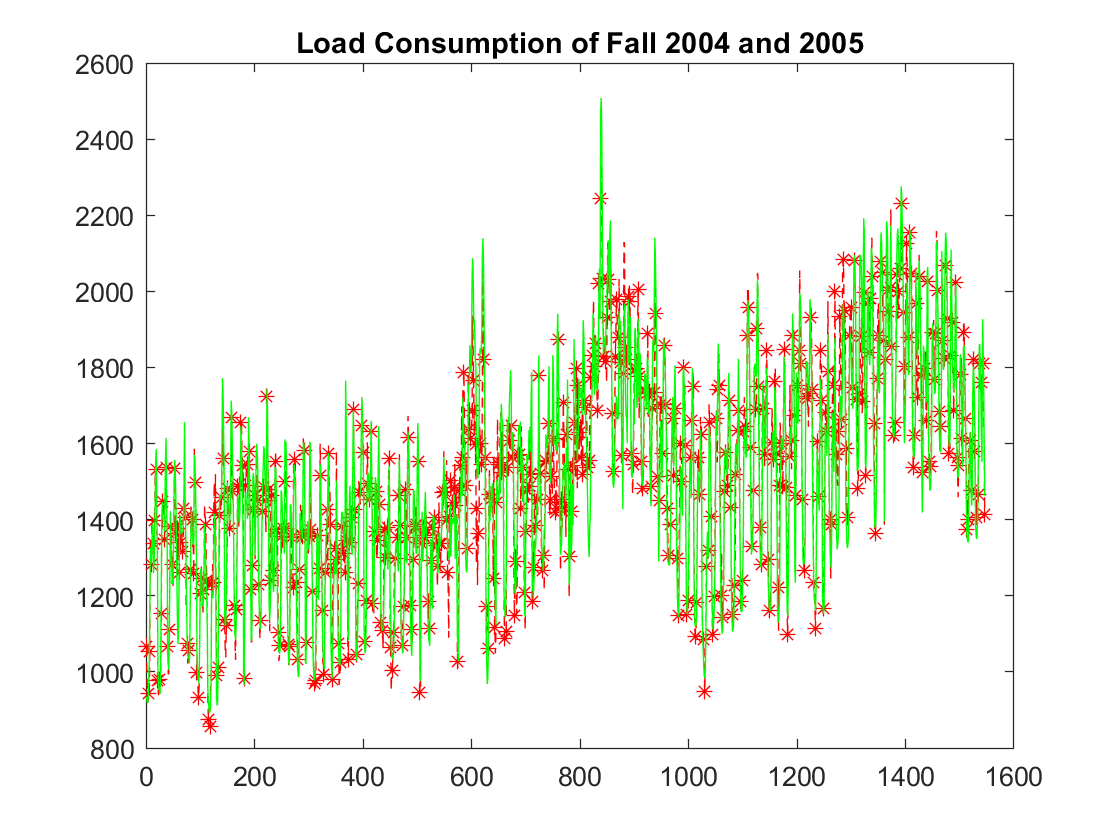

plot(1:1546,yTrain,'r--*',1:1546,yTrainTrue,'g','LineWidth',0.5,'MarkerIndices',1:3:length(yTrainTrue))

title('Load Consumption of Fall 2004 and 2005')

subtitle('Ottawa, ontario')

Unrecognized function or variable 'subtitle'.

xlabel('Hours')
ylabel('Power Consumption in KW')
hold on

plot(1547:1877,yval,'b--*',1547:1877,yvalTrue,'g','LineWidth',0.5,'MarkerIndices',1:3:length(yvalTrue))
hold on

plot(1878:2208,yTest,'k--*',1878:2208,yTestTrue,'g','LineWidth',0.5,'MarkerIndices',1:3:length(yTestTrue))
legend('Trained Anticipated','Actual Target','Validation','Actual Target','Tested Anticipated','Actual Target')
hold off

